# Second-Order Lab: Second-Order Linear DEs in MATLAB

## Student Information

## Exercise 1

Objective: Use `iode` to solve second-order linear DEs. And classify them.

Details: Consider the ODE:

(a) Use `iode` to plot six (6) numerical solutions of this equation with "random" initial data (use Method 3 above) and press-and-drag at various initial points, with some of the slopes being positive and some negative)

Use only initial points in the part of the window where `0<t<1` and `-1<x<1` and take all initial slopes between `-3` and `+3`.

Change the window to `[0,10]x[-3,3]`. Attach a cropped screenshot to your answers file.

(b) Based on the results of (a), state what percentage of solutions decay, grow, grow while oscillating, or decay while oscillating.

decay - 0%

grow - 0%

grow while oscillating - 0 %

decay whule oscillating - 100%

(c) Solve the DE and write the exact solution. Explain why this justifies your answer in (b).

`y = (e^(-t/2))*(c_1*cos(2*t)+c_2*sin(2*t)). This justifies the observation in part 2 because the (e^(-t/2)) term causes the function to decay toward 0 with increasing t while the (c_1*cos(2*t)+c_2*sin(2*t)) part of the function causes it to oscillate between positive and negative values ad infinitum. `

## Exercise 2

Consider the ODE:

Repeat (a), (b), (c) from Exercise 1 with this DE.

b) 

decay - 0%

grow - 100%

grow while oscillating - 0 %

decay whule oscillating - 0%

c)

`y = c_1*e^(((2-sqrt(3))/2)*t)+c_2*e^(((-2-sqrt(3))/2)*t). Both terms in this expression are exponential. The term (2-sqrt(3))/2 is positive while the term (-2-sqrt(3))/2 is negative, meaning that the former approaches infinity as t approaches infinity while the latter aproaches 0 as t aproaches infinity. There sum therefore approaches positive or negative infinity, depending on the sign of c_1. The absence of a sine and cosine terms confirms that we would not expect this function to oscillate. `

## Exercise 3

Consider the ODE:

Repeat (a), (b), (c) from Exercise 1 with this DE.

b) 

decay - 100%

grow - 0%

grow while oscillating - 0 %

decay whule oscillating - 0%

c)

`y = c_1*e^(((sqrt(2)-sqrt(3))/2)*t)+c_2*e^(((-sqrt(2)-sqrt(3))/2)*t)`

`In this case, both exponential terms have negative exponenents for positive t since both (sqrt(2)-sqrt(3))/2 and (-sqrt(2)-sqrt(3))/2 are negative numbers. This means that both terms approach 0 as t approaches infinity, so we expect decaying behaviour. Again, there is no sign or cosing term for any oscillating behaviour. `

## Exercise 4

Consider the fourth-order ODE:

(a) Find the general solution for this problem. You can use MATLAB to find the roots of the characteristic equation numerically with `roots`.

y = [1,2,6,2,5];
roots(y)

General solution: 

`y = e^(-t)*(c_1*sin(2*t)+c_2*cos(2*t))+c_3*sin(t)+c_4*cos(t)`

(b) Predict what percentage of solutions with random initial data will grow, decay, grow while oscillating, and decay while oscillating. Explain.

100% will only oscillate as t approach. Since the exponential term has a negative coefficient, it will approach 0 while the remaining terms oscillate between two finite numbers (bounded by the positive and negative sum of the absolute values of the c_1 and c_2). Since the dominant term is approaching 0 and the other terms oscillate between positive and negative for all t,  we expect the first term in the sume to approach 0. The remaining 2 terms, `c_3*sin(t)+c_4*cos(t), will continue to oscillate freely as t approaches infinity. This means that the expression oscillates as t approaches infinity, however it doesn't grow or decay since those require the amplitude to either approach 0 or infinity while here it is bounded by the sum of c_3 and c_4. If the terms c_3 and c_4 are 0, the amplitude will be bounded by 0, meaning we observe oscillating decay dictated by the first term.`

## Exercise 5

Objective: Classify equations given the roots of the characteristic equation.

Details: Your answer can consist of just a short sentence, as `grows` or  `decays while oscillating`.

Consider a second-order linear constant coefficient homogeneous DE with `r1` and `r2` as roots of the characteristic equation.

Summarize your conclusions about the behaviour of solutions for randomly chosen initial data when.

(a) `0 < r1 < r2`

`grows`

(b) `r1 < 0 < r2`

`grows`

(c) `r1 < r2 < 0`

`decays`

(d) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha < 0`

`decays while oscillating `

(e) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha = 0`

`oscillates without growth or decay`

(f) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha > 0`

`grows while oscillating `

## Exercise 6

Objective: Write your own second-order ODE solver.

Details: Consider the second-order ODE

Write a second-order ODE solver using the method described above.

This m-file should be a function which accepts as variables (t0,tN,y0,y1,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0, y1 are the initial conditions of the ODE, and h is the stepsize. You may also want to pass the functions into the ODE the way `ode45` does (check MATLAB lab 2). Name the function DE2_<UTORid>.m.

Note: you will need to use a loop to do this exercise. 

## Exercise 7

Objective: Compare your method with `iode`

Details: Use `iode` to plot the solution of the ODE  `y'' + exp(-t/5) y' + (1-exp(-t/5)) y = sin(2*t)` with the initial conditions  `y(0) = 1, y'(0) = 0`

Use the window to `[0,20]x[-2,2]` Without removing the figure window, plot your solution (in a different colour), which will be plotted in the same graph. 

Comment on any major differences, or the lack thereof.

f = @(t,y_p,y) -exp(-t/5)*y_p-(1-exp(-t/5))*y+sin(2*t);


ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i


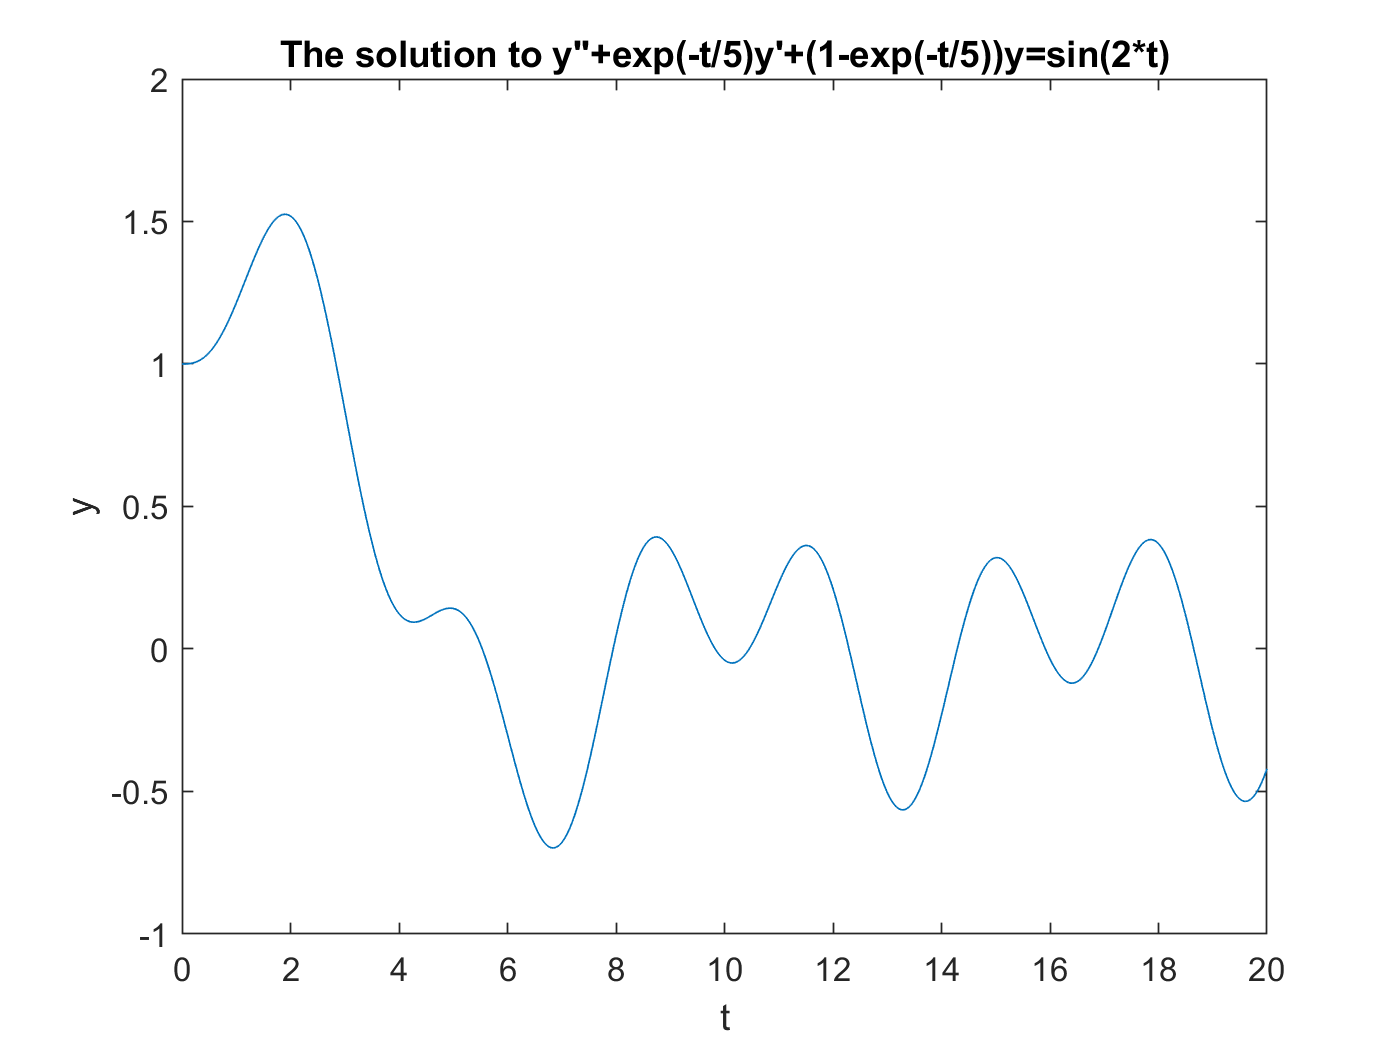

y0 = 1;
y1 = 0;
t0 = 0;
tN = 20;
h = 0.05;
t = t0:h:tN;

[t, y] = DE2_purcarur(f,t0,tN,y0,y1,h);

plot(t,y);
ylabel('y');
xlabel('t');
title("The solution to y''+exp(-t/5)y'+(1-exp(-t/5))y=sin(2*t)");
legend("iode solution", "DE2_ solution")